# Telecommunications

close all
clear all

c = 299792458;%m/s - Speed of Light
f = 145;%MHz - Frequency
L = c/f;%m - Wavelength
T_orb = 95*60;%s - Orbital Period (95 min)

h=6.626e-34;%J/s - Plank's Constant

h =     6.626e-34


E=h*f;%J

## Transmission Range


$$R=\frac{P_T G_T G_R }{16\pi^2 P_R }\lambda^2$$


dB=@(x) 10^(x/10);%Converts dB to linear
PT_dB = 27;%dB
PR_dB = -104;%dB
GT_dB = 10;%dBi
GR_dB = GT_dB;%dBi
Pt = dB(PT_dB);%W
Pr = dB(PR_dB);%W
Gt = dB(GT_dB);
Gr = dB(GR_dB);
R = (Pt*Gt*Gr*L.^2)/(16*pi^2 * Pr);%m - Linear Range of Antenna
fprintf('Maximum Range = %s meters',R)

Maximum Range = 3.407891e+25 meters

## Angles

RE = 6378;%km -  Radius of Earth
H = 550;%km - Altitude of Orbit
RO = RE+H%km - Radius of Orbit

RO = 6928


theta = acos(RE/RO);
comm_dist = RO*theta;
mu = 3.986e5;%km^3/s^2 - Standard Gravitational Parameter of Earth
V = sqrt(mu/(RO));%km/s - Orbital Velocity
% omega = V/RO;%rad/s
% T_vis = theta/omega;
% fprintf("Communication Window:\n\tDistance: %fkm\n\tTime: %f minutes",comm_dist,time/60)
T_vis=theta*sqrt(RO^3/mu);

w=7.29e-5;%rad/s - Rotation Speed of Earth
T_min = theta/w;

T_max = 2*T_min

T_ave = 3/2*T_min;
T_ave/60

ans =        137.57


how long orbit is in range per orbit * time in visibility per orbit * twice a day in minutes

T_ave/T_orb*T_vis*2/60

ans =        17.686


## Distortion

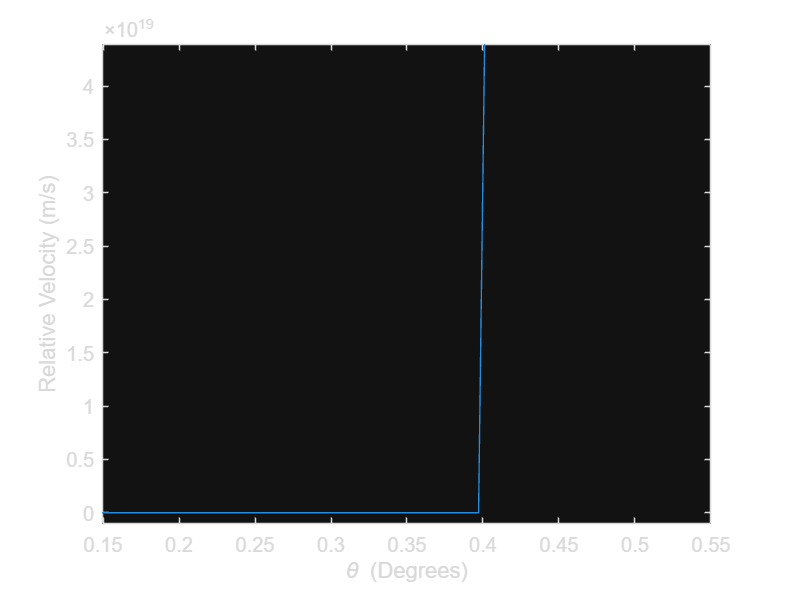

sin_rho = RE/RO;
lambda = linspace(0,theta,101);
eps = linspace(0,pi/2,length(lambda));
sin_eta = cos(eps).*sin_rho;
D = RE*sin(lambda)./sin_eta;

V_array = diff(D);
x = ones([1 length(V_array)]).*V_array./c;

% subplot(1,2,1)
figure
plot(lambda(2:end),abs(V_array))
xlabel('\theta (Degrees)')
ylabel('Relative Velocity (m/s)')
xlim([min(lambda) max(lambda)])

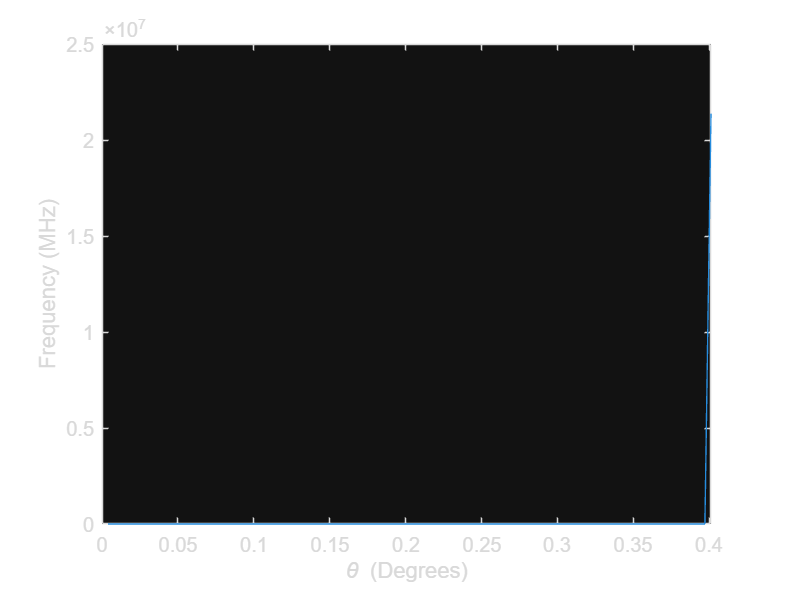

% subplot(1,2,2)
figure
plot(lambda(2:end),f/1e6*(1+x))
xlabel('\theta (Degrees)')
ylabel('Frequency (MHz)')
xlim([min(lambda) max(lambda)])

max_dist = max(abs(x))

max_dist =    1.4737e+11


sprintf("Frequency = %g Hz +/-%g Hz\nMaximum Distortion = %g%",f,f*max_dist,max_dist*100)

ans =     "Frequency = 145 Hz +/-2.13684e+13 Hz
     Maximum Distortion = 1.47368e+13"


## Link

bps = f*2;%bits/s - data rate
Ls = -147.55 + 20*log10(2705)+20*log10(f)

Ls = -35.6793

L = Ls-20

L = -55.6793

69.6*(1-10^(L/10))

ans = 69.5998

Ladd=5;%dB
T_DL=290+93;
T_UL=10+580;
Ts=[T_DL;T_UL];
Eb_N0 = PT_dB + GT_dB + GR_dB - Ls - Ladd + 228.6 - 10*log10(Ts)%-10*log10(R);

Eb_N0 =       -37.969
      -39.846


% fprintf("Can transmit %g GB",bytes*1e-9)

save Telecom.mat %f bytes time bits